5. Let $u\left(x\right)=\frac{1}{x+1}$. Approximate u on [0,2] using n equally spaced subintervals for n=2,5,10 using

a) polynomial interpolation with the Vandermonde matrix and a polynomial of degree n

b) polynomial interpolation with the the Lagrange formula and a polynomial of degree n

Plot your results and discuss.

a) By using the Vandermonde martix

In order to find polynomial that pas throug all the point are given, we need to first set up a polynomial:

$P\left(x\right)=a_0 +a_1 x+a_2 x^2 +\ldotp \ldotp \ldotp +a_k x^k$            (4)

Then plug all the points given into equation (4)

Suppose the points are:


$$\left(x_0 ,y_0 \right)\left(x_2 ,y_2 \right)\left(x_3 ,y_3 \right)\ldotp \ldotp \ldotp \left(x_k ,y_k \right)$$


As a result we will get:


$$\left\lbrace \begin{array}{c}
P\left(x_0 \right)=a_0 +a_1 x_0 +a_2 {x_0 }^2 +\ldotp \ldotp \ldotp +a_k {x_0 }^k =y_0 \\
P\left(x_1 \right)=a_0 +a_1 x_1 +a_2 {x_1 }^2 +\ldotp \ldotp \ldotp +a_k {x_1 }^k =y_1 \\
\vdots \\
P\left(x_k \right)=a_0 +a_1 x_k +a_2 {x_k }^2 +\ldotp \ldotp \ldotp +a_k {x_k }^k =y_k 
\end{array}\right.$$


And if we write them as a matrix:

$\left\lbrack \begin{array}{cccccc}
1 & x_0  & x_0^2  & x_0^3  & \cdots  & x_0^k \\
1 & x_1  & x_1^2  & x_1^3  & \cdots  & x_1^k \\
1 & x_2  & x_2^2  & x_2^3  & \cdots  & x_2^k \\
\vdots  & \vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
\vdots  & \vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
1 & x_k  & x_k^2  & x_k^3  & \cdots  & x_k^k 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
\vdots \\
a_k 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
\vdots \\
y_k 
\end{array}\right\rbrack$        (5)

Let

$V=\left\lbrack \begin{array}{cccccc}
1 & x_0  & x_0^2  & x_0^3  & \cdots  & x_0^k \\
1 & x_1  & x_1^2  & x_1^3  & \cdots  & x_1^k \\
1 & x_2  & x_2^2  & x_2^3  & \cdots  & x_2^k \\
\vdots  & \vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
\vdots  & \vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
1 & x_k  & x_k^2  & x_k^3  & \cdots  & x_k^k 
\end{array}\right\rbrack$, $a=\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
\vdots \\
a_k 
\end{array}\right\rbrack$and $y=\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
\vdots \\
y_k 
\end{array}\right\rbrack$

equation (5) can be written as $\mathrm{Va}=y$

V is called Vandermonde

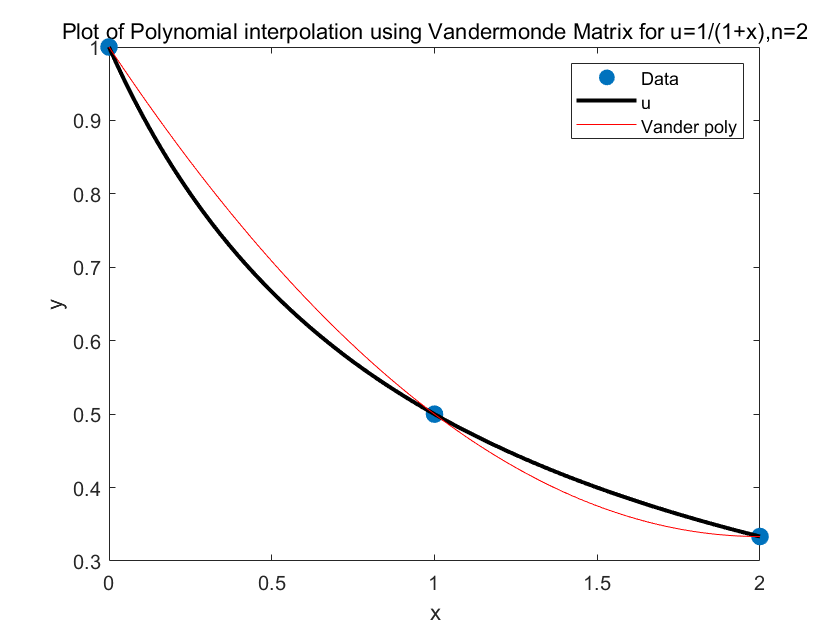

clear
%define the interval
a=0;
b=2;

%Vandermonde matrix
n = 2; % number of intervals
[x2V,y2V,xfine2V,u_Vander_fine2V,a_vec2V]=van(a,b,n);
plotA(x2V,y2V,xfine2V,u_Vander_fine2V,n)

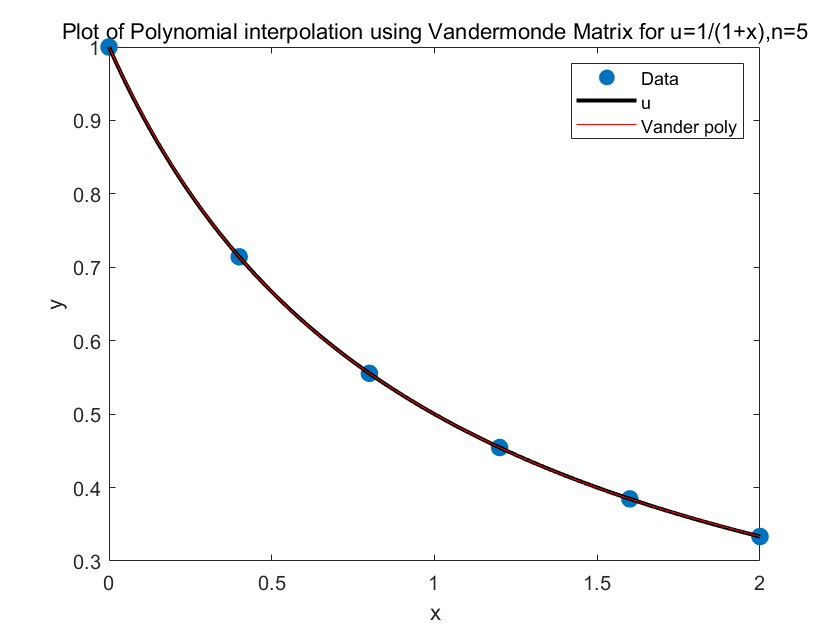


n = 5; % number of intervals
[x5V,y5V,xfine5V,u_Vander_fine5V,a_vec5V]=van(a,b,n);
plotA(x5V,y5V,xfine5V,u_Vander_fine5V,n)

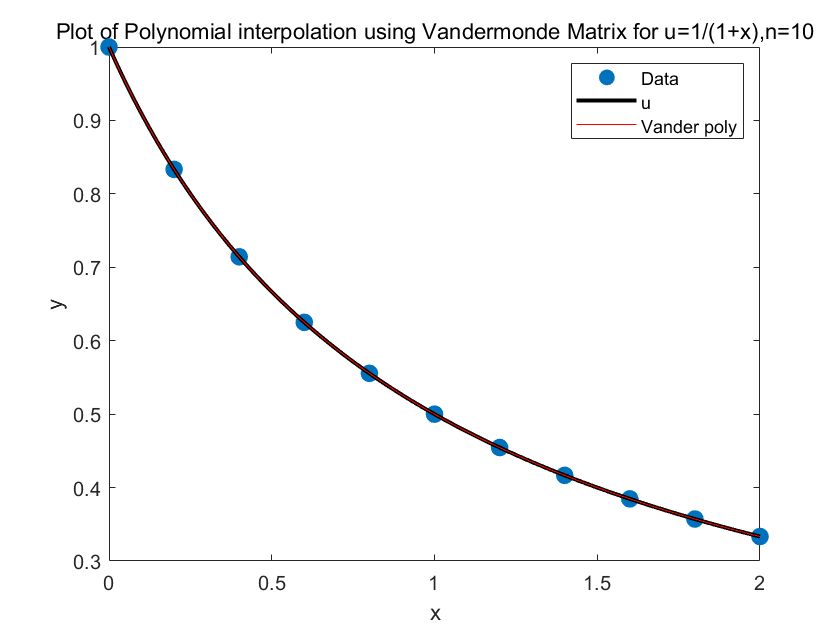


n = 10; % number of intervals
[x10V,y10V,xfine10V,u_Vander_fine10V,a_vec10V]=van(a,b,n);
plotA(x10V,y10V,xfine10V,u_Vander_fine10V,n)

From the graph above we could see as the interval point increasing the polynomial are almost become coincide with the original function u(x).

b)By using the Lagrange fomular

The Lagrange fomular is:

$y_k =p\left(x_k \right)$                (6)

$p\left(x_k \right)=y_0 \ell_0 \left(x\right)+y_1 \ell_1 \left(x\right)+\cdots {+y}_n \ell_n \left(x\right)$            (7)


$$\ell_0 \left(x\right)=\frac{\left(x-x_0 \right)\left(x-x_1 \right)\cdots \left(x-x_{k-1} \right)\left(x-x_{k+1} \right)\cdots \left(x-x_n \right)}{\left(x_k -x_0 \right)\left(x_k -x_1 \right)\cdots \left(x_k -x_{k-1} \right)\left(x_k -x_{k+1} \right)\cdots \left(x_k -x_n \right)}$$


where can be write as

$\ell_j \left(x\right)=\prod_{k=0,k\not= j}^n \frac{\left(x-x_k \right)}{\left(x_j -x_k \right)}$            (8)

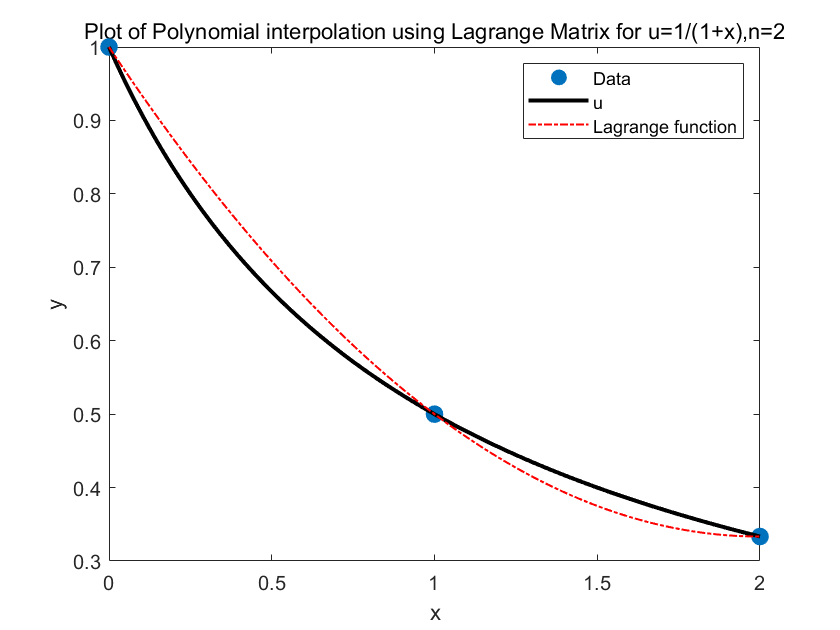

%Lagrange fomular
n = 2; % number of intervals
[x2L,y2L,xfine2L,u_Lagrange2L]=lan(a,b,n);
plotAN(x2L,y2L,xfine2L,u_Lagrange2L,n)

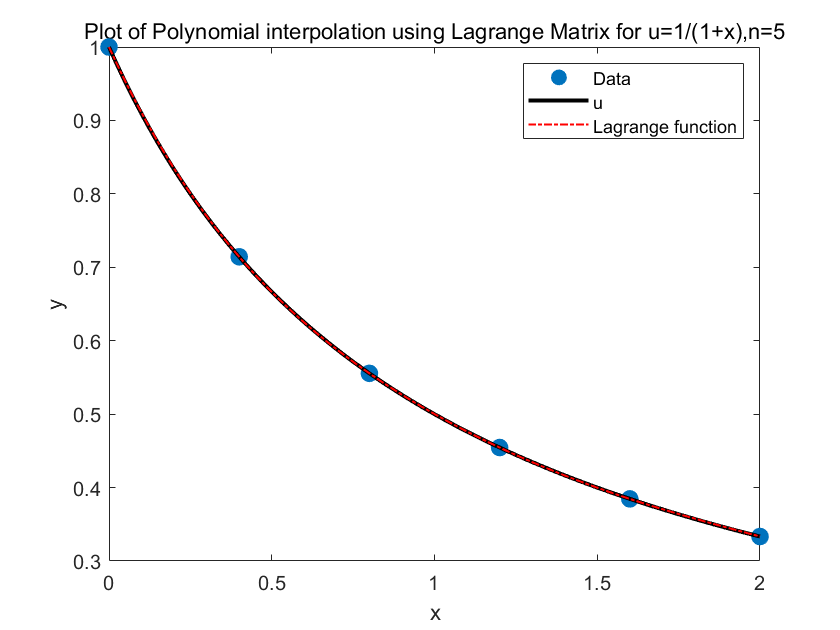


n = 5; % number of intervals
[x5L,y5L,xfine5L,u_Lagrange5L]=lan(a,b,n);
plotAN(x5L,y5L,xfine5L,u_Lagrange5L,n)

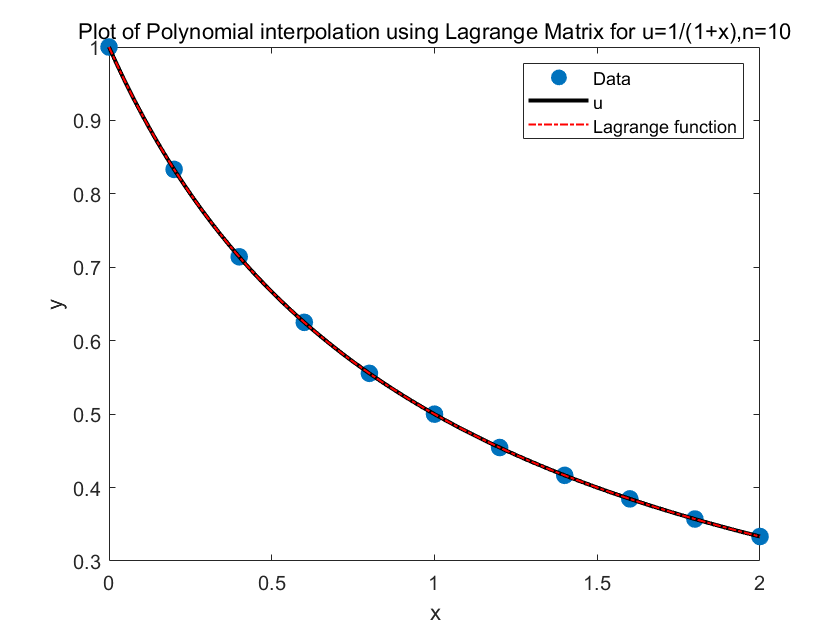


n = 10; % number of intervals
[x10L,y10L,xfine10L,u_Lagrange10L]=lan(a,b,n);
plotAN(x10L,y10L,xfine10L,u_Lagrange10L,n)

From the graph above we could see as that the polynomial compute from Lagrange method is also looks like coinside with the true value;

By compute the error of them

err_Vandermonde_n_2 = sum(abs(u_Vander_fine2V-u(xfine2V)),'all')

err_Vandermonde_n_2 = 4.5646

err_Vandermonde_n_5 = sum(abs(u_Vander_fine5V-u(xfine5V)),'all')

err_Vandermonde_n_5 = 0.0643

err_Vandermonde_n_10 = sum(abs(u_Vander_fine10V-u(xfine10V)),'all')

err_Vandermonde_n_10 = 1.3101e-04

err_Lagrange_n_2 = sum(abs(u_Lagrange2L-u(xfine2L)),'all')

err_Lagrange_n_2 = 4.5646

err_Lagrange_n_5 = sum(abs(u_Lagrange5L-u(xfine5L)),'all')

err_Lagrange_n_5 = 0.0643

err_Lagrange_n_10 = sum(abs(u_Lagrange10L-u(xfine10L)),'all')

err_Lagrange_n_10 = 1.3101e-04

As result, we could find that, as n increading the error of both approximation decreased.

function [x,y,xfine,u_Vander_fine,a_vec]=van(a,b,n)
%function of computing the Vandermonde martix and correspounding
%coefficients
%take input a,b,and n
%out put x: the x coodinate of data point according to n
%out put y: the y coodinate of data point that compute from x
%xfine: a finer grid of x
%u_Vander_fine: approximate the polynomial using the coefficient compute from V and y
%a_vec: vector a
    h = (b-a)/n; 
    x = a + (0:n)*h; % define the x values
    y = u(x); % define the corresponding y values as y_j = u(x_j)
    Vmat = zeros(length(x));
    for ii=1:length(x)
        % loop over the data points
        for jj=1:length(x) 
            % loop over the columns of the Vandermonde martix
            Vmat(ii,jj) = x(ii)^(jj-1); 
            % since matlab indices starts at 1, so we need to subtract 1
        end
    end
    rr_form     = rref([Vmat,y(:)]);
    a_vec       = rr_form(:,end); % peeling off the last column
    xfine         = a:0.01:b;%define a finer grid x
    u_Vander_fine = a_vec(1)*ones(size(xfine));
    for jj=1:n
        %compute the polynomial from vector a
        u_Vander_fine = u_Vander_fine + a_vec(jj+1)*xfine.^(jj);
    end
end



function [x,y,xfine,u_Lagrange]=lan(a,b,n)
%function of compute the Lagrange fomular
%input a, b and n
%outpout
%out put x: the x coodinate of data point according to n
%out put y: the y coodinate of data point that compute from x
%xfine: a finer grid of x
%u_Lagrange:  approximate the polynomial 
% using the coefficient compute Lagrange fomular
    h = (b-a)/n;
    x = a + (0:n)*h; % define the x values
    y = u(x); % define the corresponding y values as y_j = u(x_j)
    N          = length(x);
    xfine       = a:0.01:b; % define the finer x values
    u_Lagrange  = zeros(size(xfine));
    for k = 1:N
        %loop each k from equation (6)
        w = ones(size(xfine));
        for j = [1:k-1 k+1:N] % This loop the index from equation (8)
            w = (xfine-x(j))./(x(k)-x(j)).*w;
        end
        u_Lagrange = u_Lagrange + w*y(k); 
        % This adds up each y_k*l_k(x) term, equation (7)
    end
end

function []=plotA(x,y,xfine,u_Vander_fine,n)
%function of plot the polynomial from Vandermonde martix
%take input:
%x: the x coodinate of data point according to n
%y: the y coodinate of data point that compute from x
%xfine: a finer grid of x
%u_Vander_fine: approximate the polynomial using the coefficient compute from V and y
%n
    plot(x,y,'.','MarkerSize', 30)%plot the data
    hold on;
    plot(xfine,u(xfine),'k', 'LineWidth',2)%plot the true value
    plot(xfine, u_Vander_fine, 'r')%plot the polynomial
    xlabel('x');ylabel('y');
    legend('Data','u', 'Vander poly')
    title(['Plot of Polynomial interpolation using ' ...
        'Vandermonde Matrix for u=1/(1+x),n=',num2str(n)])
    hold off
end

function []=plotAN(x,y,xfine,u_Lagrange,n)
%function of plot the polynomial from Lagrange fomular
%take input:
%x: the x coodinate of data point according to n
%y: the y coodinate of data point that compute from x
%xfine: a finer grid of x
%u_Lagrange: approximate the polynomial using the coefficient compute Lagrange
%n
    plot(x,y,'.','MarkerSize',30);%plot the data
    hold on;
    plot(xfine,u(xfine),'k', 'LineWidth',2);%plot the true value
    plot(xfine,u_Lagrange,'-.r','LineWidth',1)%plot the polynomial
    xlabel('x');ylabel('y');
    legend('Data','u','Lagrange function')
    title(['Plot of Polynomial interpolation using' ...
        ' Lagrange Matrix for u=1/(1+x),n=',num2str(n)])
    hold off
end

function [ut]=u(x)
%true function
    ut=1./(x+1);
end
